## Data

% 
clear all; close all; clc;
set_env;
%

% Data --------------------------------------------------------------
% Constants
eps_0 = 8.85e-12; 			% F/m , permittivity of vacuum

% Geometry
% tp_0 = 25e-6; 				% m   , initial thickness of polymer layer
% l_0 = 50e-3 / 2; 			% m   , initial length of polymer layer

% Acrylic dielectric
% mu_DE = 35; 				% -   		, Shear modulus
% lambda_DE = 8; 			% -   		, Max stretch
% epsilon_p = 4.5 * eps_0;	% F/m 		, permittivity of poymeric layer
% EBD_p = 70e6; 			    % V / m     , Breakdown field
% nu = 0.3; 				%  -        , Poisson's ratio of polymer
% Y_p = 4.5e5               % Pa        , Young's modulus

% Fluid 
% epsilon_f = 80 * eps_0; 		% F/m , permittivity of fluid (seawater)
% EBD_f = 30e3 / 0.5e-3                       % V / m   , Breakdown field

% Operational limits -------------------------------------------------
% VBD = EBD_f * [h_f + epsilon_f / epsilon_p * (x - h_f)];
% h_f is the "thickness" of the fluid layer	 where the term in [] is minimum

% epsilon_i = lambda_DE - 1; 	% - , Max strain


% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f positive

% Geometry of the capacitor
syms x l_0 w tp_0 xi positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms Uel(x) V F(x,V) C(x)

% Strains: eps1 along the polymer, eps3 thickness strain of the polymer
syms epsilon_1(x) epsilon_3(x) 

assume(nu > 0 & "real")
assume(Y_p > 0 & 'real')
assume(epsilon_p > 0 & 'real')
assume(epsilon_f > 0 & 'real')
assume(x > 0 & 'real')

assume(w > 0 & 'real')
assume(tp_0 > 0 & 'real')
assume(xi > 0 & 'real')

assume(l_0 > 0)
assumeAlso(l_0 >= xi)
assumeAlso(l_0, 'real')
% 
assume(EBD_p, 'real')
assume(EBD_f, 'real')


## Equations

% Equations ---------------------------------------------------------
% epsilon_1(x) = sqrt(1 + x^2 / (4 * l_0^2)) - 1
% epsilon_3(x) = epsilon_1(x) * nu / (nu - 1)

% Stresses
sigma_1(x) = - Y_p * epsilon_1(x) / (nu^2 - 1)

$$sigma\_1(x) = -\frac{Y_{p}\,\epsilon_{1}\left(x\right)}{\nu^{2}-1}$$

sigma_3(x) = - Y_p * epsilon_1(x) * nu / (nu^2 - 1)

$$sigma\_3(x) = -\frac{Y_{p}\,\nu \,\epsilon_{1}\left(x\right)}{\nu^{2}-1}$$


% Geometry ------------------------------
l(x) = l_0 * (1 + epsilon_1(x));
t_p(x) = tp_0 * (1 + epsilon_3(x));
t_f(x) = (x / 2 - 2 * t_p) * (l_0 - xi) / l_0; 
A = l * w;
dA = w * (1 + epsilon_1(x)) ; % * dxsi

% Range limit
x_max = rhs(isolate(subsstrain(epsilon_1(x)) == 0.05, x))

$$x\_max = \frac{\sqrt{41}\,l_{0}}{10}$$


% Polymer infinitesimal capacitance
dCp = dA * epsilon_p / t_p

$$dCp(x) = \frac{\epsilon_{p}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}$$

% Fluid infinitesimal capacitance
dCf = dA * epsilon_f / t_f

$$dCf(x) = \frac{\epsilon_{f}\,l_{0}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}{\left(\frac{x}{2}-2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-\xi \right)}$$


% Total infinitesimal capacitance
dC = ((2 / dCp) + (2 / dCf))^(-1)

$$dC(x) = \frac{1}{\frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{\epsilon_{p}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}+\frac{2\,\left(\frac{x}{2}-2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(l_{0}-\xi \right)}{\epsilon_{f}\,l_{0}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)}}$$

## Capacitance

% Total capacitance +++++++++++++++++++++++++++++++++++++++++++++++++
C(x) = int(dC, xi)

$$C(x) = \frac{\epsilon_{f}\,l_{0}\,w\,\log\left(\epsilon_{p}\,\left(l_{0}-\xi \right)\,\left(4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)}$$

C(x) = simplify(subs(C(x), xi, l_0) - subs(C(x), xi, 0))

$$C(x) = \frac{\epsilon_{f}\,l_{0}\,w\,\left(\epsilon_{1}\left(x\right)+1\right)\,\left(\log\left(-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)-\log\left(\epsilon_{p}\,l_{0}\,\left(4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\right)}{4\,{\mathrm{tp}}_{0}-x+4\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)}$$


% Min and max capacitance
Cmax = vpa(subs(sdata(C,'all'), x, 0), 4)

$$Cmax(x) = -5.285e-10+1.738e-9\,\mathrm{i}$$

Cmin = vpa(subs(sdata(C,'all'), x, sdata(x_max)), 4)

$$Cmin(x) = 2.327e-11$$

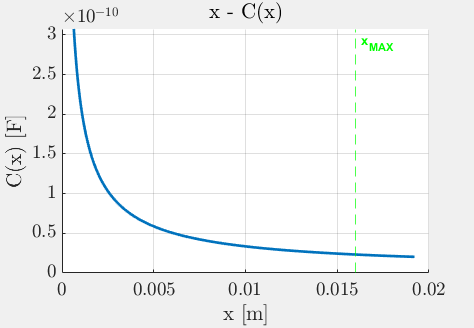

% Plot x - C(x)
myfig(1,"x - C(x)");
hold on
fplot(x, sdata(C(x), 'all'), [0, 1.2 * sdata(x_max)], 'LineWidth', 2)
xline(sdata(x_max), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontWeight','bold')
hold off
title("x - C(x)")
xlabel("x [m]")
ylabel("C(x) [F]")

## Max voltage

% Max voltage
% Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)
Vmax(x) = 2 * t_p / epsilon_p * min(epsilon_p * EBD_p, epsilon_f * EBD_f)

$$Vmax(x) = \frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\,\min\left(\left[{\mathrm{EBD}}_{f}\,\epsilon_{f},{\mathrm{EBD}}_{p}\,\epsilon_{p}\right],\left[\right],2,\text{"omitnan"},{\mathrm{EBD}}_{f}\notin \mathbb{R}\vee {\mathrm{EBD}}_{p}\notin \mathbb{R}\vee \epsilon_{f}\notin \mathbb{R}\vee \epsilon_{p}\notin \mathbb{R}\right)}{\epsilon_{p}}$$

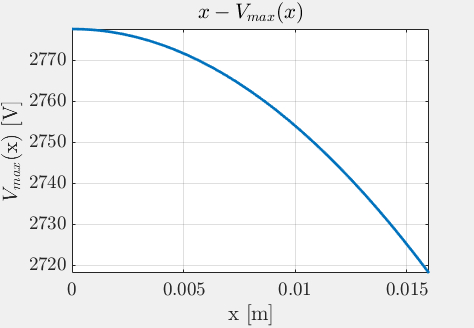


% Plot x - Vmax(x)
myfig(2,"x - Vmax(x)");
fplot(x, sdata(Vmax(x), 'all'), [0, sdata(x_max)], 'LineWidth', 2)
title("$x - V_{max}(x)$")
xlabel("x [m]")
ylabel("$V_{max}$(x) [V]")

## Force

% Force
Uel(x) = 2 * sdata(1 / 2 * (sigma_1 * epsilon_1) * w * t_p * l, 'all')

$$Uel(x) = -\frac{9375\,{\left(\sqrt{400\,x^{2}+1}-1\right)}^{2}\,\sqrt{400\,x^{2}+1}\,\left(\frac{3\,\sqrt{400\,x^{2}+1}}{7}-\frac{10}{7}\right)}{91}$$


F(x,V) = diff(Uel, x) - V^2 / 2 * diff(sdata(C, 'all'), x)


% Min and max force for V = 0 and V = Vmax
FVmin = vpa(F(x, 0), 4);
FVmax= vpa(F(x, sdata(Vmax, 'all')), 4);

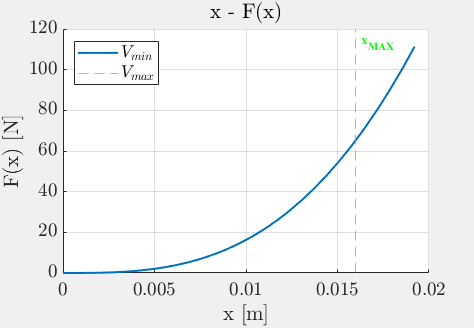

% Plot x - F(x)
myfig(3,"x - F(x)")
hold on
fplot(x, FVmin, [0, 1.2 * sdata(x_max)], 'LineWidth', 1.5)
% fplot(x, FVmax, [0, 1.2 * sdata(x_max)], 'LineWidth', 1.5)
xline(sdata(x_max), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontName', 'times new roman', 'FontWeight','bold')
hold off
legend(["$V_{min}$", "$V_{max}$"], "Location", "northwest")
title("x - F(x)")
xlabel("x [m]")
ylabel("F(x) [N]")

## Q - V

% Plot Q - V
x_vec = linspace(sdata(x_max)/100, sdata(x_max), 20);
C_vec = subs(sdata(C, 'all'), x_vec);
Vmax_vec = subs(sdata(Vmax, 'all'), x_vec);
Q_vec = C_vec .* Vmax_vec;
Cmax = vpa(subs(sdata(C,'all'), x, sdata(x_max)/100), 4)

$$Cmax(x) = 1.06e-9$$

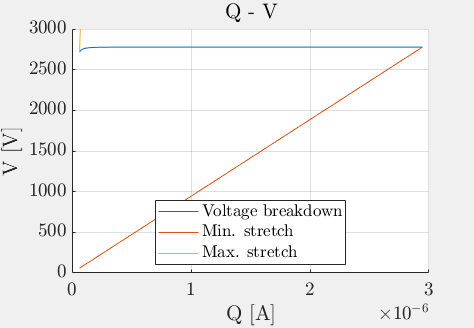

myfig(4,"Q - V"); clf
hold on
plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown")
plot(Q_vec, Q_vec ./ Cmax, 'DisplayName', "Min. stretch")
plot(Q_vec, Q_vec ./ Cmin, 'DisplayName', "Max. stretch")
hold off
legend('Location','best')
xlabel("Q [A]")
ylabel("V [V]")
ylim([0,3000])
title("Q - V")